## Read Navigation from Parrot Mambo

Version: August 16, 2019

## Reference

[Read and Plot Navigation data using MATLAB® Support Package for Parrot® Drones](https://www.mathworks.com/help/supportpkg/parrotio/ref/read-and-plot-navigation-data-matlab-parrot.html)

## Preamble

Using WiFi, connect to the mini drone, then create a drone object:

p = parrot();

Take-off

takeoff(p);

Create an animated figure:

f = figure;
hx = animatedline('Color', 'r', 'LineWidth', 2);
hy = animatedline('Color', 'g', 'LineWidth', 2);
hz = animatedline('Color', 'b', 'LineWidth', 2);
title('DroneSpeed v/s Time');
xlabel('Time (in s)');
ylabel('Speed (in m/s)');
legend('XSpeed', 'YSpeed', 'ZSpeed');

Plot navigation data:

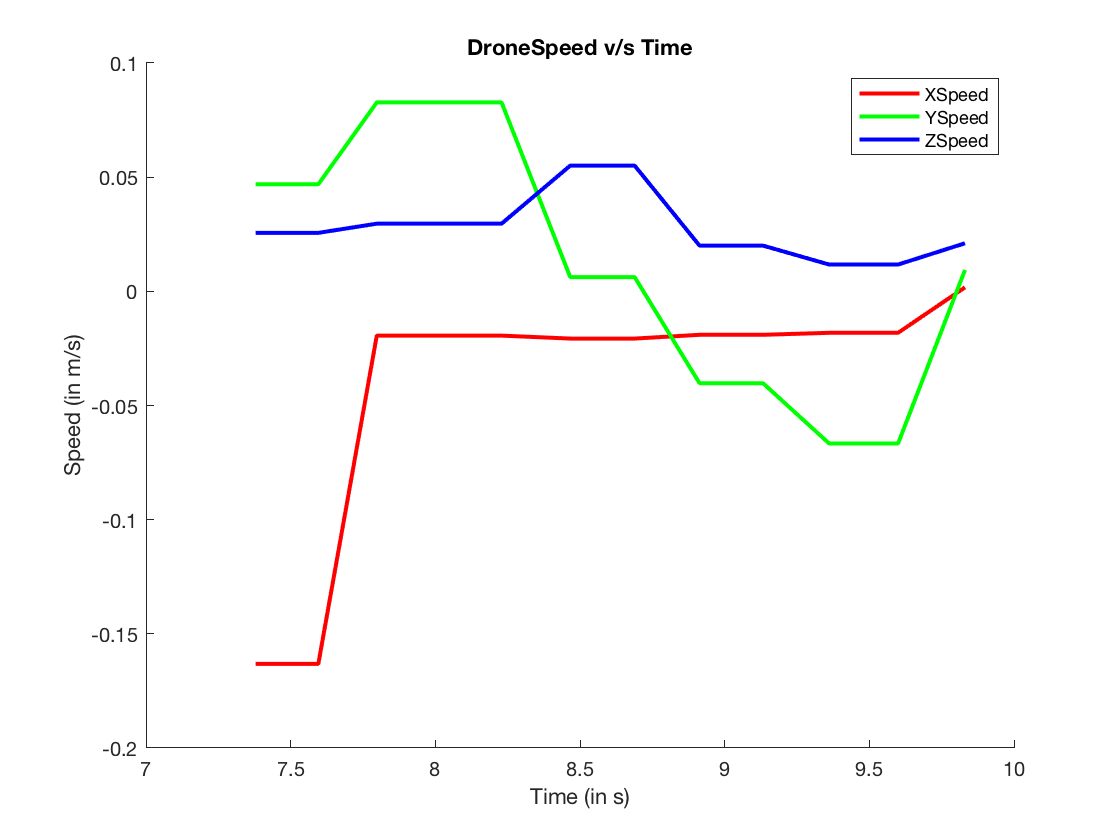

flightTime = 10;
tObj = tic;
data = [];
% fly along a circlular path
move(p, 5, 'Roll', deg2rad(4), 'RotationSpeed', deg2rad(120));
while(p.BatteryLevel > 10 && toc(tObj) < flightTime)
    % move(p, 'Pitch', deg2rad(-4), 'Roll', deg2rad(4));
    takeoff(p);
    speed = readSpeed(p);
    tStamp = toc(tObj);
    addpoints(hx, tStamp, speed(1));
    addpoints(hy, tStamp, speed(2));
    addpoints(hz, tStamp, speed(3));
    data = [data ; [tStamp speed] ];
    drawnow;
    pause(0.1);
end

Land:

land(p);

Clean-up:

clear p;

Save data to file:

fileID = fopen('/Users/joaquin/Desktop/realdata6.txt','w');
fprintf(fileID,'%6.8f %6.8f %6.8f %6.8f\n',data');
fclose(fileID)

ans = 0